clc;
clear;
% 设置参数
fc = 77e+9;              
Nc = 128;  
c = 3e8; 
rangeRes = 1; %距离分辨率为1
B  = c/(2*rangeRes);               
maxR = 200;              
tau_max = 2*maxR/c;
Tchirp = 5.5*tau_max;    
S  = B/Tchirp; 
Ns = 1024;
Fs = Ns/Tchirp;
f_IFmax = S * tau_max;


%动态目标生成
R_init = [25;50;100]; 
v  =    [50;25;50];

n = 0:Ns*Nc-1;
t = n.*(Tchirp/Ns);
tau = 2*(R_init+v*t)./(c+v) ;
Rx = cos(2*pi*fc.*(t-tau) + S*pi.*mod((t-tau), Tchirp).^2);
Rx = sum(Rx);
%混频的发射信号
Tx = cos(2*pi*fc.*(t)+pi*S.*mod(t, Tchirp).^2);
Fx = fc+mod(t,Tchirp).*S;


混频部分

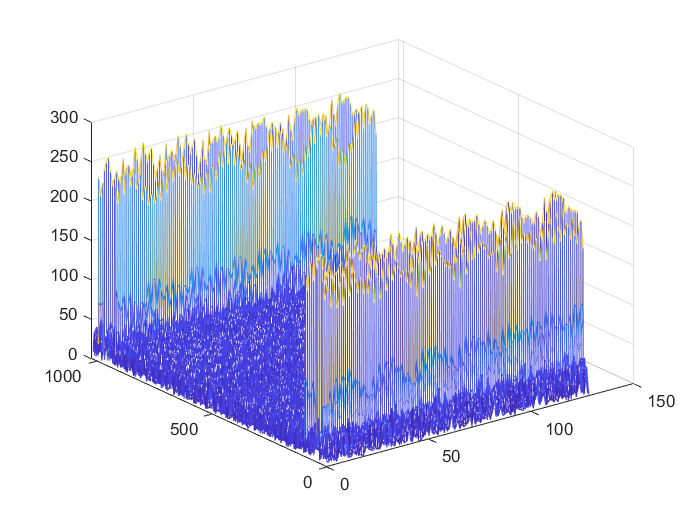

Mix = Tx.*Rx;
Mix = reshape(Mix, Ns, Nc); %当加入多普勒效应时，中频信号为调频信号，reshape后每个chirp之间的相位差由相移和频移同时构成，无法解算速度？
Mix_dft = abs(fft(Mix));

mesh(Mix_dft);

测距部分


%变采样数据为二维做fft得到二维距离图像
n = 0:Ns*Nc-1;
range_axis = rangeRes * n(1:ceil(maxR/rangeRes));
sig = reshape(Mix,[Ns,Nc]);
sig_fft = abs(fft(sig));

mesh(sig_fft);

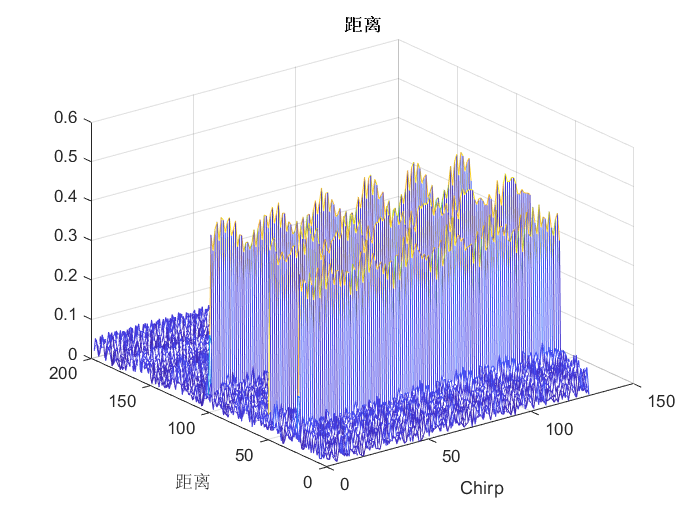

sig_fft = sig_fft(1:ceil(maxR/rangeRes),: )/(Ns/2);

mesh((1:Nc),range_axis,sig_fft);

xlabel('Chirp');
ylabel('距离');
title('距离');

速度维度的解算

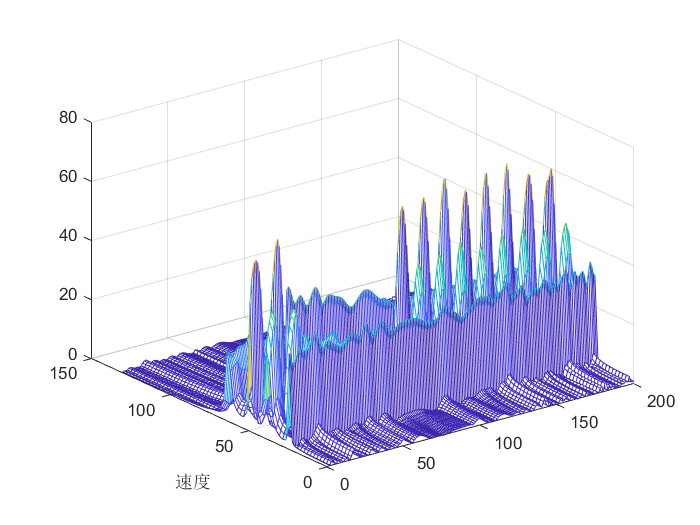


vres=(c/fc)/(2*Nc*Tchirp);
v_axis = vres * n(1:Nc/2); %正速度
sig2 = sig';
sig2_fft = abs(fft(sig2));
sig2_fft = sig2_fft(1:Nc/2,:);

mesh((1:ceil(maxR/rangeRes)),v_axis,sig2_fft(:,1:ceil(maxR/rangeRes)));
ylabel('速度');

二维fft,速度与距离的解算

sig_fft3 = abs(fft2(sig,Ns,Nc));
sig_fft3 = fftshift (sig_fft3);

ns  = linspace(-Ns/2,Ns/2-1,Ns); %fft以及fftshift之后，点的标位和偏移问题
range_axis = ns*rangeRes

range_axis =   -512  -511  -510  -509  -508  -507  -506  -505  -504  -503  -502  -501  -500  -499  -498  -497  -496  -495  -494  -493  -492  -491  -490  -489  -488  -487  -486  -485  -484  -483  -482  -481  -480  -479  -478  -477  -476  -475  -474  -473  -472  -471  -470  -469  -468  -467  -466  -465  -464  -463


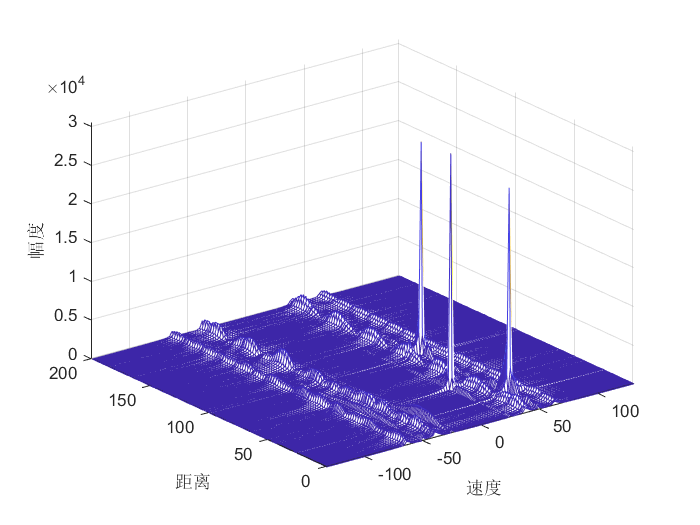

nc = linspace(-Nc/2,Nc/2-1,Nc);
v_axis = nc*vres;
mesh(v_axis,range_axis(Ns/2:Ns/2+ceil(maxR/rangeRes)),sig_fft3(Ns/2:Ns/2+ceil(maxR/rangeRes),:));
xlabel('速度'); ylabel('距离'); zlabel('幅度');